
clear

D = 40 % Diámetro exterior mm

D = 40

d = 25.4 % Diámetro agujero mm

d = 25.4000

h = 6.35 % Grosor placa mm

h = 6.3500

l = 50 % Longitud vertical mm

l = 50

w = 40 % Ancho placa mm 

w = 40

Area = (D-d)*h % Área de contacto mm^2

Area = 92.7100


% https://www.elesa-ganter.es/es/esp/Juntas--Horquillas--DIN71752

## Fatiga

%SoporteBiela=readtable("MatLab cinetica\Reacciones biela\A3-soporte-biela.txt","Delimiter"," ");
%SoporteBiela=readtable("MatLab cinetica\Reacciones biela\B3-soporte-biela.txt","Delimiter"," ");
SoporteBiela=readtable("MatLab cinetica\Reacciones soporte\C3-soporte-biela.txt","Delimiter"," ");


SoporteBiela.Properties.VariableNames=["T","Fz","Fy","Fx","F","Mz","My","Mx","M"];

vectorTiempo=SoporteBiela.T;

SoporteBielaFx=SoporteBiela.Fy;
SoporteBielaFy=SoporteBiela.Fz;
SoporteBielaFz=SoporteBiela.Fx;

max(abs(SoporteBielaFx))

ans = 6.4128e+03

max(abs(SoporteBielaFy))

ans = 0.8904

max(abs(SoporteBielaFz))

ans = 0.0710


max(SoporteBiela.F)

ans = 6.4128e+03


Sut = 630 % MPa -> 100 ksi 

Sut = 630

Sy = 530 % MPa

Sy = 530

kt = Kt(d,w) % Factor geométrico concentración esfuerzos

kt = 2.0648


neuberF=0.07; %Corregir neuber
neuberT=0.055;

radioMuesca=0.2; %inches
qFlexion=1/(1+neuberF/sqrt(radioMuesca));
qTorsion=1/(1+neuberT/sqrt(radioMuesca));
Kf=1+qFlexion*(kt-1);


SoporteBielaFx=SoporteBielaFx/2

SoporteBielaFx = 	1.0e+03 *

   -2.2732
   -2.3947
   -2.5158
   -2.6361
   -2.7552
   -2.8726
   -2.9876
   -3.1012
   -3.2064
   -3.1876



sigma=SoporteBielaFx/Area

sigma =   -24.5193
  -25.8298
  -27.1362
  -28.4340
  -29.7182
  -30.9853
  -32.2247
  -33.4505
  -34.5850
  -34.3824


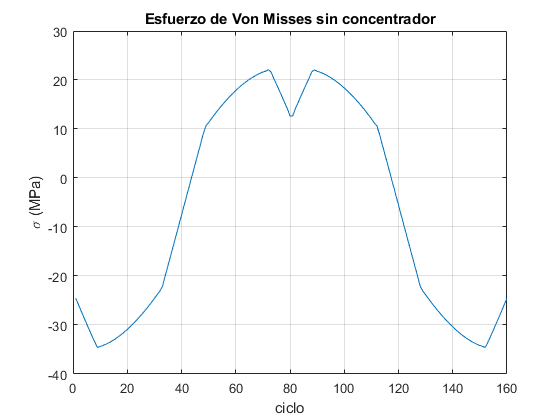



plot(sigma)
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses sin concentrador")
grid on

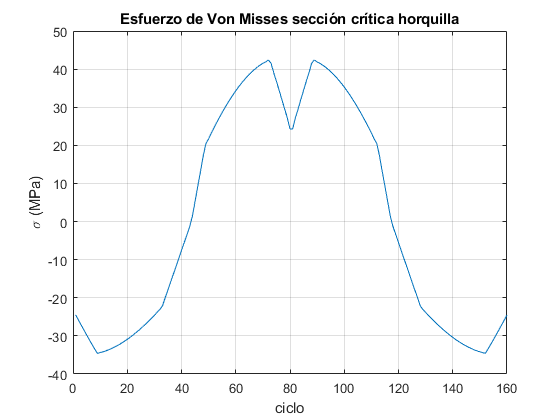



sigma(sigma>0)=sigma(sigma>0)*Kf;

plot(sigma)
xlabel("ciclo")
ylabel("\sigma (MPa)")
title("Esfuerzo de Von Misses sección crítica horquilla")
grid on




Fcar = 0.7 % Carga, carga axial

Fcar = 0.7000


A_95=0.05*Area

A_95 = 4.6355

d_eq=sqrt(A_95/0.0766)

d_eq = 7.7792


Ftam=1.189*(d_eq)^(-0.097)

Ftam = 0.9745

%Ftam = 1.189 * (d) ^ (-0.097) % Tamaño, 8 mm < d <= 250 mm

Fsup = 4.51 * (Sut) ^ (-0.265) % Superficie, rolado en frío

Fsup = 0.8172

Ftem = 1 % Temperatura, T <= 450 °C

Ftem = 1

Fcon = 0.814 % Confiabilidad, 99%

Fcon = 0.8140

SeSC = 0.5*Sut

SeSC = 315

Se = SeSC * Fsup * Fcar * Ftem * Ftam * Fcon

Se = 142.9373


Sigma_Alternante=0.5*(max(sigma)-min(sigma))

Sigma_Alternante = 38.4981

Sigma_Medio=0.5*(max(sigma)+min(sigma))

Sigma_Medio = 3.9131

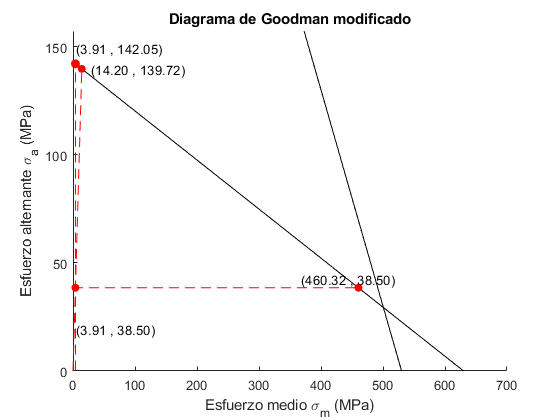

FS1 = 3.6898

FS2 = 3.6291

FS3 = 117.6341

FactorMinimo = 3.6291



%Factor seguridad
%N = ( (Sigma_med / Sut) + ((Sigma_alt) / Se) ) ^ (-1)

FactorMinimo = diagramaGoodman(Sigma_Alternante,Sigma_Medio,Sut,Sy,Se,true)

function [kt] = Kt(d,w)
    c1 = 3.0039;
    c2 = 3.753 * (d / w);
    c3 = 7.9735 * (d / w) ^ 2;
    c4 = 9.2659 * (d / w) ^ 3;
    c5 = 1.8145 * (d / w) ^ 4;
    c6 = 2.9684 * (d / w) ^ 5; 
    kt = c1 - c2 + c3 - c4 + c5 + c6;
end


function FSMin=diagramaGoodman(EsigmaA,EsigmaM,ESut,ESy,ESe,tension)
syms x1 x2 x3 x4 x5

if(tension)
sigmaA=EsigmaA;
sigmaM=EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy-x;
goodManM=@(x)  Se-x.*Se./Sut;
lineaC=@(x)     sigmaA.*x./sigmaM;

Fr=sigmaA.*x1/sigmaM==Se-x1./Sut.*Se;
Fq= Sy-x2==sigmaA;
Fq2=Se-x5./Sut.*Se==sigmaA;

FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSy2=double(solve(Fq2,x5));

if(FSy2<FSy)
    FSy=FSy2;
end




figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[0 Sy],"k")
fplot(goodManM,[0 Sut],"k")
fplot(lineaC,[0 FSm],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[0 FSy],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(1.1*sigmaM,0.5*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(1.1*sigmaM,1.05*goodManM(sigmaM),sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(2*FSm,1*goodManM(FSm),sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(0.8*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.1])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado")
FS1=goodManM(sigmaM)/sigmaA
FS2=sqrt(FSm^2+goodManM(FSm)^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]);

else
    
    
sigmaA=EsigmaA;
sigmaM=-EsigmaM;
Sut=ESut;
Sy=ESy;
Se=ESe;
lineaF=@(x)    Sy+x;
goodManM=@(x)  Se;
lineaC=@(x)     sigmaA.*x./sigmaM;
Fr=sigmaA.*x1/sigmaM==Se;
Fq= Sy+x2==sigmaA;
Fc2=Se==Sy+x3;
FSm=double(solve(Fr,x1));
FSy=double(solve(Fq,x2));
FSn=double(solve(Fc2,x3));
figure()
scatter(sigmaM,sigmaA,"r","filled")
hold on
fplot(lineaF,[-Sy 0],"k")
fplot(goodManM,[FSn 0],"k")
fplot(lineaC,[FSm 0],"r--")
stem(sigmaM,goodManM(sigmaM),"r--","filled")
scatter(FSm,goodManM(FSm),"r","filled")
scatter(FSy,sigmaA,"r","filled")
fplot(sigmaA,[FSy 0],"r--")
scatter(sigmaM,sigmaA,"r","filled")
text(4*sigmaM,1.1*sigmaA,sprintf('(%.2f , %.2f)', sigmaM,sigmaA))
text(3*sigmaM,1*Se,sprintf('(%.2f , %.2f)', sigmaM,goodManM(sigmaM)))
text(1.5*FSm,0.95*Se,sprintf('(%.2f , %.2f)', FSm,goodManM(FSm)))
text(1.1*FSy,1.1*sigmaA,sprintf('(%.2f , %.2f)', FSy,sigmaA))
hold off
ylim([0 Se*1.2])
xlabel("Esfuerzo medio \sigma_m (MPa)")
ylabel("Esfuerzo alternante \sigma_a (MPa)")
title("Diagrama de Goodman modificado (Compresión)")
ax=gca;
ax.YAxisLocation = 'right';
FS1=Se/sigmaA
FS2=sqrt(FSm^2+Se^2)/sqrt(sigmaM^2+sigmaA^2)
FS3=FSy/sigmaM
FSMin=min([FS1 FS2 FS3]); 
end
end